# Discrete-Time Systems: From Block Diagrams to Feedback

Interactive MATLAB Live Script. Run section by section (Ctrl+Enter), change the highlighted parameters, and re-run to see what happens. All code is toolbox-free (base MATLAB only); a few optional cells use the Symbolic Math Toolbox or xcorr and are guarded with checks.

## Learning objectives

1. Describe a discrete-time system and draw its block diagram (delay, gain, adder). 2. Relate continuous-time ZIR / impulse response / ZSR to their discrete-time counterparts. 3. Use the z-transform, transfer function, poles/zeros and the stability criterion. 4. Compute convolution, cross-correlation and auto-correlation. 5. Apply them to real problems: smoothing, echo, sonar ranging, hidden-period detection. 6. Understand feedback and how it moves poles (and can destroy stability).

clear; close all; clc;
set(0,'DefaultAxesFontSize',12);
set(0,'DefaultLineLineWidth',1.5);
rng(1);   % reproducible random numbers

## 1. What is a system, and how do we diagram it?

A system is anything that transforms an input signal into an output signal. In discrete time: y[n] = T{ x[n] }. Most systems in this course are described by a linear constant-coefficient difference equation (LCCDE):


$$y[n] = -\sum_{k=1}^{N} a_k\, y[n-k] \;+\; \sum_{k=0}^{M} b_k\, x[n-k]$$


## 1.1 The three building blocks

- Unit delay (z^-1): output is the input one sample earlier.

- Gain (a): multiplies the signal by a constant.

- Adder (+): sums signals sample by sample.

Any LCCDE can be drawn with only these three blocks. Example: the first-order recursive system y[n] = a*y[n-1] + x[n].

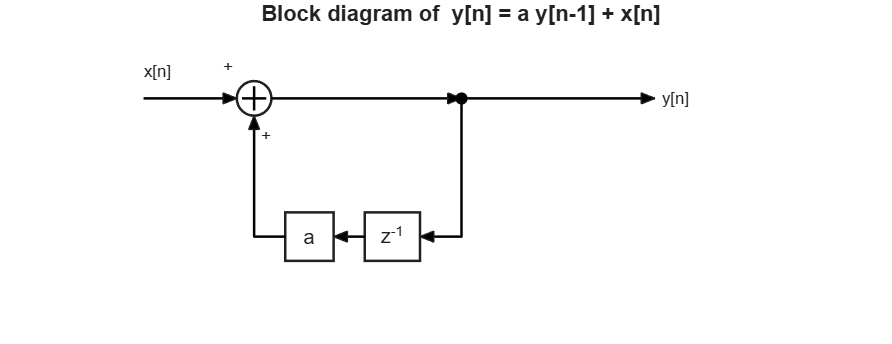

figure('Position',[100 100 780 300]);
ax = axes; hold(ax,'on'); axis(ax,[0 10 0 4]); daspect(ax,[1 1 1]); axis(ax,'off');

drawArrow(ax,[0.4 1.75],[3 3]);          text(ax,0.4,3.4,'x[n]');
drawSum(ax,2,3,0.25);                    text(ax,1.55,3.45,'+'); text(ax,2.1,2.45,'+');
drawArrow(ax,[2.25 5],[3 3]);
plot(ax,5,3,'k.','MarkerSize',22);
drawArrow(ax,[5 7.8],[3 3]);             text(ax,7.9,3,'y[n]');
drawArrow(ax,[5 5 4.4],[3 1 1]);                      % feedback path, down then left
drawBox(ax,4,1,0.8,0.7,'z^{-1}');
drawArrow(ax,[3.6 3.15],[1 1]);
drawBox(ax,2.8,1,0.7,0.7,'a');
drawArrow(ax,[2.45 2 2],[1 1 2.75]);
title(ax,'Block diagram of  y[n] = a y[n-1] + x[n]');

## 1.2 Simulating the diagram

The diagram is a recipe: at every n, take the delayed output, multiply by a, add the input. Change a and the pulse length below.

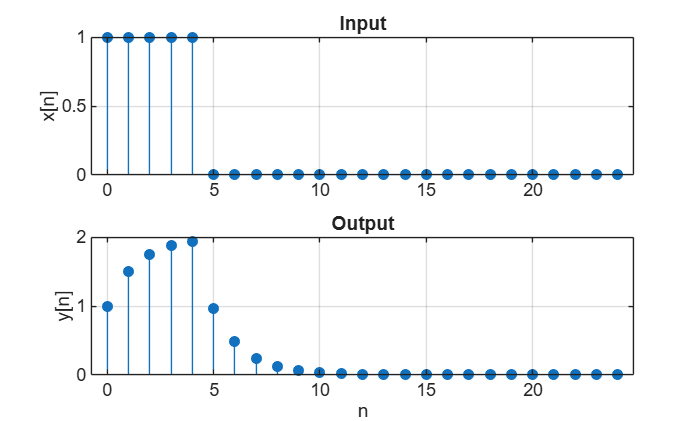

a = 0.5;                       % <-- feedback gain, try 0.9, -0.5, 1.1
N = 25;  n = 0:N-1;
x = double(n < 5);             % rectangular input pulse of length 5

y = zeros(1,N);  yprev = 0;    % yprev stores y[n-1] (the delay block)
for k = 1:N
    y(k) = a*yprev + x(k);
    yprev = y(k);
end

figure;
subplot(2,1,1); stem(n,x,'filled'); ylabel('x[n]'); grid on; title('Input');
subplot(2,1,2); stem(n,y,'filled'); ylabel('y[n]'); xlabel('n'); grid on; title('Output');

## 1.3 Classifying systems (numerically)

A system is linear if T{c1*x1 + c2*x2} = c1*T{x1} + c2*T{x2}, and time-invariant if delaying the input by D delays the output by D. A system is causal if the output at n does not depend on future inputs. A zero error means 'property holds'.

sys  = @(x) filter(1,[1 -0.5],x);            % y[n] = 0.5 y[n-1] + x[n]
x1 = randn(1,40);  x2 = randn(1,40);  c1 = 2;  c2 = -3;  D = 7;

% linearity
linErr = max(abs( sys(c1*x1+c2*x2) - (c1*sys(x1)+c2*sys(x2)) ))

linErr = 8.8818e-16


% time invariance
x1d = [zeros(1,D) x1(1:end-D)];  y1 = sys(x1);
tiErr = max(abs( sys(x1d) - [zeros(1,D) y1(1:end-D)] ))

tiErr = 0


% causality: change the FUTURE input, the past output must not change
x3 = x1;  x3(21:end) = 0;  y3 = sys(x3);
causalErr = max(abs( y3(1:20) - y1(1:20) ))

causalErr = 0


% counter-examples
sysSq = @(x) x.^2;                           % nonlinear
sysTV = @(x) (0:numel(x)-1).*x;              % time-varying: y[n] = n x[n]
linErr_square = max(abs( sysSq(c1*x1+c2*x2) - (c1*sysSq(x1)+c2*sysSq(x2)) ))

linErr_square = 55.5923

yTV = sysTV(x1);
tiErr_nx = max(abs( sysTV(x1d) - [zeros(1,D) yTV(1:end-D)] ))

tiErr_nx = 14.2041

## 2. ZIR, impulse response and ZSR: continuous vs. discrete

In continuous time (CTSP) we decompose the total response of an LTI system as:


$$y(t) = y_{zi}(t) + y_{zs}(t), \qquad y_{zs}(t) = \int_{-\infty}^{\infty} x(\tau)\, h(t-\tau)\, d\tau$$


where h(t) is the response to the impulse delta(t).

The discrete-time (DTSP) counterparts are:


$$y[n] = y_{zi}[n] + y_{zs}[n], \qquad y_{zs}[n] = \sum_{k=-\infty}^{\infty} x[k]\, h[n-k]$$


- Zero-input response (ZIR), y_zi[n]: response with x[n] = 0 caused only by the initial conditions (y[-1], y[-2], ...). It is the 'natural' response and depends only on the poles.

- Impulse response h[n]: the output when x[n] = delta[n] (the unit sample, 1 at n = 0, else 0) and zero initial conditions. It fully characterizes an LTI system.

- Zero-state response (ZSR), y_zs[n]: response to the input x[n] with zero initial conditions. y_zs[n] = x[n] * h[n] = sum_k x[k] h[n-k] (convolution SUM).

- Total response: y[n] = y_zi[n] + y_zs[n].

The key simplification compared to CT: the integral becomes a sum, and delta[n] is a genuine, finite-height sample (not a distribution).

Example: y[n] = 0.8 y[n-1] + x[n], with initial condition y[-1] = 2 and input x[n] = u[n] (unit step).

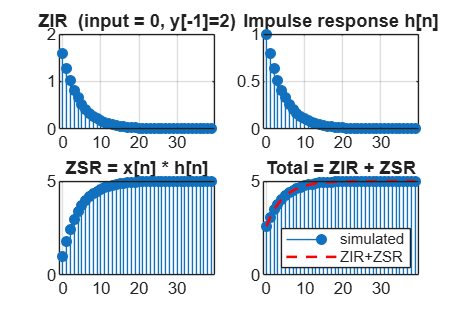

N = 40;  n = 0:N-1;
b = 1;  a = [1 -0.8];                      % y[n] - 0.8 y[n-1] = x[n]
yinit = 2;                                 % y[-1]
x     = ones(1,N);                         % unit step
delta = [1 zeros(1,N-1)];                  % unit sample

zir   = runSystem(b,a,zeros(1,N),yinit);   % no input, only initial condition
h     = runSystem(b,a,delta,0);            % impulse response (zero state)
zsr_c = conv(x,h);  zsr_c = zsr_c(1:N);    % ZSR = x * h  (convolution)
ytot  = runSystem(b,a,x,yinit);            % direct simulation of everything

figure('Position',[100 100 900 600]);
subplot(2,2,1); stem(n,zir,'filled'); title('ZIR  (input = 0, y[-1]=2)'); grid on;
subplot(2,2,2); stem(n,h,'filled');   title('Impulse response h[n]');     grid on;
subplot(2,2,3); stem(n,zsr_c,'filled'); title('ZSR = x[n] * h[n]');       grid on;
subplot(2,2,4); stem(n,ytot,'filled'); hold on; plot(n,zir+zsr_c,'r--');
title('Total = ZIR + ZSR'); legend('simulated','ZIR+ZSR','Location','southeast'); grid on;


fprintf('max |total - (ZIR+ZSR)| = %.2e\n', max(abs(ytot-(zir+zsr_c))));

max |total - (ZIR+ZSR)| = 2.66e-15


fprintf('Analytical ZIR 2*0.8^(n+1) check: %.2e\n', max(abs(zir - 2*0.8.^(n+1))));

Analytical ZIR 2*0.8^(n+1) check: 1.11e-16


fprintf('Analytical h[n] = 0.8^n check:    %.2e\n', max(abs(h - 0.8.^n)));

Analytical h[n] = 0.8^n check:    5.55e-17


Observation: both the ZIR and h[n] decay like 0.8^n. They share the same 'mode' because both are governed by the pole at z = 0.8. The ZIR only needs the poles and the initial state; the ZSR needs h[n] and the input.

## 3. The z-transform and the stability criterion

## 3.1 Definition and key pairs


$$X(z) = \mathcal{Z}\{x[n]\} = \sum_{n=-\infty}^{\infty} x[n]\, z^{-n}, \qquad z = r e^{j\omega}\in\mathbb{C}$$


The sum only converges for some values of z: the Region of Convergence (ROC). The ROC is part of the answer; the same X(z) expression with a different ROC is a different signal.

Inverse transform (in practice we use partial fractions or long division rather than the contour integral):


$$x[n] = \frac{1}{2\pi j}\oint_C X(z)\, z^{n-1}\, dz$$


How to compute X(z) by hand, step by step:

Step 1: write down x[n] for every n. Step 2: multiply each sample by z^-n. Step 3: sum. Step 4: if the sum is infinite, recognise a geometric series and state when it converges.

Example A (finite-length signal): x[n] = {1, 2, 3, 2, 1} for n = 0..4. Each sample just becomes a coefficient of z^-n:


$$X(z) = 1 + 2z^{-1} + 3z^{-2} + 2z^{-3} + z^{-4}, \qquad \mathrm{ROC}: z \neq 0$$


Example B (right-sided exponential): x[n] = a^n u[n]. Use the geometric series sum_{n=0}^{inf} q^n = 1/(1-q) for `q` < 1, with q = a z^-1:


$$X(z) = \sum_{n=0}^{\infty} a^n z^{-n} = \sum_{n=0}^{\infty} (a z^{-1})^n = \frac{1}{1 - a z^{-1}} = \frac{z}{z-a}, \qquad |a z^{-1}| < 1 \;\Rightarrow\; |z| > |a|$$


Example C (left-sided exponential): x[n] = -a^n u[-n-1]. Same algebraic result but a different ROC:


$$X(z) = \frac{1}{1 - a z^{-1}}, \qquad \mathrm{ROC}: |z| < |a|$$


Evaluate Example A numerically. On the unit circle z = exp(j*w), X(z) is the discrete-time Fourier transform:

x = [1 2 3 2 1];                 % x[n], n = 0..4
n = 0:numel(x)-1;
Xz = @(z) sum(x .* z.^(-n));     % X(z) = sum x[n] z^-n

X_at_2 = Xz(2)                   % = 1 + 2/2 + 3/4 + 2/8 + 1/16 = 3.0625

X_at_2 = 3.0625

X_at_1 = Xz(1)                   % = sum of samples = 9 (DC gain)

X_at_1 = 9

X_dtft = Xz(exp(1j*0.5))         % DTFT at w = 0.5 rad/sample

X_dtft = 4.1014 - 6.3876i

Useful pairs and properties (causal signals):

- delta[n]  [-](http://-) 1

- a^n u[n]  [-](http://-) 1 / (1 - a z^-1), ROC `z` > `a`

- u[n]  [-](http://-) 1 / (1 - z^-1), ROC `z` > 1

- n a^n u[n]  [-](http://-) a z^-1 / (1 - a z^-1)^2

- Delay: x[n-k]  [-](http://-) z^-k X(z)

- Convolution: x[n] * h[n]  [-](http://-) X(z) H(z) (the reason the z-transform is so useful: convolution becomes multiplication)

Check numerically that the sum really equals the closed form inside the ROC:

a  = 0.8;
z0 = 1.5*exp(1j*0.7);              % |z0| = 1.5 > |a|, inside the ROC
n  = 0:300;
X_sum    = sum(a.^n .* z0.^(-n));
X_closed = 1/(1 - a/z0);
fprintf('Sum of series : %.6f %+.6fi\n', real(X_sum),    imag(X_sum));

Sum of series : 1.263483 -0.733191i


fprintf('Closed form   : %.6f %+.6fi\n', real(X_closed), imag(X_closed));

Closed form   : 1.263483 -0.733191i


Optional: symbolic computation (needs Symbolic Math Toolbox).

if ~isempty(ver('symbolic'))
    syms n z integer
    Xs = ztrans((4/5)^n, n, z)                    % z/(z-4/5)
    xs = iztrans(z/(z-1)/(z-1/2), z, n)           % inverse transform by partial fractions
else
    disp('Symbolic Math Toolbox not installed - skipping.');
end

## 3.2 Transfer function from the difference equation

Take the z-transform of the LCCDE (zero initial conditions) and divide output by input:


$$H(z) = \frac{Y(z)}{X(z)} = \frac{b_0 + b_1 z^{-1} + \cdots + b_M z^{-M}}{1 + a_1 z^{-1} + \cdots + a_N z^{-N}}, \qquad h[n] = \mathcal{Z}^{-1}\{H(z)\}$$


Worked example. Start from the difference equation used in the code below:


$$y[n] - 1.2\,y[n-1] + 0.8\,y[n-2] = x[n] + 0.5\,x[n-1]$$


Step 1: z-transform both sides using the delay property x[n-k] [-](http://-) z^-k X(z):


$$Y(z)\left(1 - 1.2 z^{-1} + 0.8 z^{-2}\right) = X(z)\left(1 + 0.5 z^{-1}\right)$$


Step 2: divide, then multiply top and bottom by z^2 to get polynomials in z:


$$H(z) = \frac{1 + 0.5 z^{-1}}{1 - 1.2 z^{-1} + 0.8 z^{-2}} = \frac{z(z+0.5)}{z^2 - 1.2 z + 0.8}$$


Step 3: zeros are the roots of the numerator, poles the roots of the denominator:


$$\text{zeros: } z = 0,\; -0.5 \qquad \text{poles: } z = 0.6 \pm j0.663, \quad |p| = \sqrt{0.8} \approx 0.894$$


The roots of the numerator are the zeros, and the roots of the denominator are the poles. Frequency response: H(e^{j w}) is H(z) evaluated on the unit circle.

b = [1 0.5];                    % numerator   (coefficients of z^0, z^-1, ...)
a = [1 -1.2 0.8];               % denominator: y[n] = 1.2y[n-1] - 0.8y[n-2] + x[n] + 0.5x[n-1]

poles = roots([a zeros(1,max(0,numel(b)-numel(a)))])  %#ok<NOPTS>

poles =    0.6000 + 0.6633i
   0.6000 - 0.6633i


zeros_ = roots([b zeros(1,max(0,numel(a)-numel(b)))]) %#ok<NOPTS>

zeros_ =          0
   -0.5000


radius = abs(poles)

radius =     0.8944
    0.8944


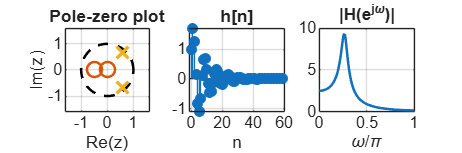


w  = linspace(0,pi,512);
Hw = (exp(-1j*w(:)*(0:numel(b)-1))*b(:)) ./ (exp(-1j*w(:)*(0:numel(a)-1))*a(:));
N  = 60;  h = filter(b,a,[1 zeros(1,N-1)]);

figure('Position',[100 100 1000 330]);
subplot(1,3,1); pzPlot(gca,b,a); title('Pole-zero plot');
subplot(1,3,2); stem(0:N-1,h,'filled'); grid on; title('h[n]'); xlabel('n');
subplot(1,3,3); plot(w/pi,abs(Hw)); grid on; title('|H(e^{j\omega})|'); xlabel('\omega/\pi');

## 3.2b Inverse z-transform by partial fractions

Given X(z) in powers of z^-1, expand in partial fractions, then invert each term using a^n u[n] [-](http://-) 1/(1 - a z^-1). Example:


$$X(z) = \frac{1}{(1 - 0.5 z^{-1})(1 - 0.8 z^{-1})} = \frac{A}{1 - 0.5 z^{-1}} + \frac{B}{1 - 0.8 z^{-1}}$$


Cover-up rule: A = [(1-0.5z^-1) X(z)] evaluated at z^-1 = 1/0.5 = 2, and B likewise at z^-1 = 1/0.8:


$$A = \frac{1}{1 - 0.8\cdot 2} = -\frac{5}{3}, \qquad B = \frac{1}{1 - 0.5/0.8} = \frac{8}{3}$$



$$x[n] = \frac{8}{3}(0.8)^n - \frac{5}{3}(0.5)^n, \qquad n \geq 0 \quad (\text{ROC } |z| > 0.8)$$


Check against the impulse response of the corresponding filter:

a  = conv([1 -0.5],[1 -0.8]);                 % denominator polynomial in z^-1
A  = 1/(1 - 0.8/0.5);   B = 1/(1 - 0.5/0.8);  % cover-up rule
n  = 0:15;
x_formula = A*0.5.^n + B*0.8.^n;
x_filter  = filter(1,a,[1 zeros(1,15)]);      % inverse transform by running the system
max_error = max(abs(x_formula - x_filter))

max_error = 5.5511e-16

## 3.3 Stability criterion

BIBO stability: every bounded input gives a bounded output. For an LTI system this is equivalent to sum_n `h[n]` < infinity.

In the z-domain, for a causal system: the system is BIBO stable if and only if ALL poles lie strictly inside the unit circle (`p` < 1). Equivalently, the ROC `z` > max|p| includes the unit circle. Poles on the circle give marginal stability (bounded for some inputs, unbounded for others, e.g. resonance); poles outside give growing responses.

For the first-order system H(z) = 1/(1 - a z^-1), the single pole is at z = a, so stable if and only if `a` < 1. Try different values:

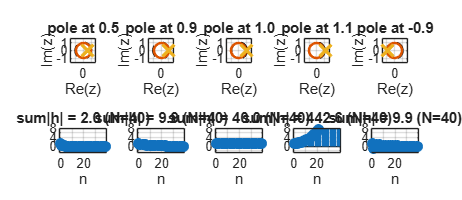

aVals = [0.5 0.9 1.0 1.1 -0.9];       % <-- change these
N = 40;  n = 0:N-1;
figure('Position',[100 100 1200 520]);
tiledlayout(2,numel(aVals),'TileSpacing','compact');
for i = 1:numel(aVals)
    a1 = aVals(i);
    h  = filter(1,[1 -a1],[1 zeros(1,N-1)]);
    nexttile(i);               pzPlot(gca,1,[1 -a1]); title(sprintf('pole at %.1f',a1));
    nexttile(numel(aVals)+i);  stem(n,h,'filled'); grid on; xlabel('n');
    title(sprintf('sum|h| = %.1f (N=%d)',sum(abs(h)),N));
    ylim([-3 8]);
end

Second-order systems: A(z) = 1 + a1 z^-1 + a2 z^-2. The Jury / stability-triangle conditions are  `a2` < 1 and  `a1` < 1 + a2. The cell below brute-forces the pole locations on a grid and compares with the triangle.

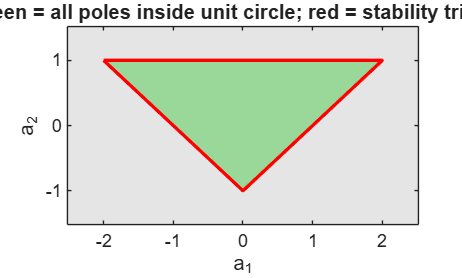

[A1,A2] = meshgrid(linspace(-2.5,2.5,201), linspace(-1.5,1.5,121));
stable  = false(size(A1));
for i = 1:numel(A1)
    stable(i) = all(abs(roots([1 A1(i) A2(i)])) < 1);
end
figure; imagesc(A1(1,:),A2(:,1),stable); axis xy; hold on;
plot([-2 2 0 -2],[1 1 -1 1],'r','LineWidth',2);
colormap([0.9 0.9 0.9; 0.6 0.85 0.6]); xlabel('a_1'); ylabel('a_2');
title('Green = all poles inside unit circle; red = stability triangle');

Poles of a second-order resonator: r*exp(+/- j*theta). Radius r sets the decay rate, angle theta sets the oscillation frequency. Try r = 0.7, 0.95, 1.02.

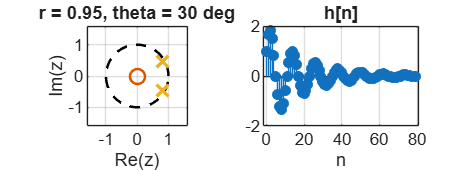

r = 0.95;  theta = pi/6;                 % <-- change me
a = [1 -2*r*cos(theta) r^2];
N = 80;  h = filter(1,a,[1 zeros(1,N-1)]);
figure('Position',[100 100 900 330]);
subplot(1,2,1); pzPlot(gca,1,a); title(sprintf('r = %.2f, theta = %.0f deg',r,theta*180/pi));
subplot(1,2,2); stem(0:N-1,h,'filled'); grid on; title('h[n]'); xlabel('n');

## 4. Basic operations: convolution, cross-correlation, auto-correlation

## 4.1 Convolution


$$y[n] = (x * h)[n] = \sum_{k=-\infty}^{\infty} x[k]\, h[n-k] = \sum_{k=-\infty}^{\infty} h[k]\, x[n-k]$$


Recipe: (1) flip h to get h[-k]; (2) shift it by n; (3) multiply with x[k]; (4) sum. Repeat for each n. If x has Nx samples and h has Nh samples, the result has Nx + Nh - 1 samples.

Worked example by hand. x[n] = {1, 2, 3, 2, 1} (n = 0..4) and h[n] = {1, 0.5, 0.25} (n = 0..2). Output length = 5 + 3 - 1 = 7, so n = 0..6. For each n, only products with k and n-k both inside the supports survive:


$$y[0] = x[0]h[0] = 1$$



$$y[1] = x[0]h[1] + x[1]h[0] = 0.5 + 2 = 2.5$$



$$y[2] = x[0]h[2] + x[1]h[1] + x[2]h[0] = 0.25 + 1 + 3 = 4.25$$



$$y[3] = x[1]h[2] + x[2]h[1] + x[3]h[0] = 0.5 + 1.5 + 2 = 4$$



$$y[4] = x[2]h[2] + x[3]h[1] + x[4]h[0] = 0.75 + 1 + 1 = 2.75$$



$$y[5] = x[3]h[2] + x[4]h[1] = 0.5 + 0.5 = 1$$



$$y[6] = x[4]h[2] = 0.25$$


Sanity check: sum(y) = sum(x) * sum(h) = 9 * 1.75 = 15.75 (the DC gain rule, from X(1)H(1)).

Four equivalent ways to compute a convolution:

1. Direct sum (above, and the myconv function below). 2. Flip-and-slide: reverse h, slide it right one sample at a time, multiply overlapping samples and add. 3. Matrix form: y = T x, where T is a Toeplitz matrix built from h (each column is h shifted down by one). 4. Polynomial multiplication: X(z)H(z) = Y(z), coefficients of the product polynomial in z^-1 are y[n].

x = [1 2 3 2 1];                 % defined for n = 0..4
h = [1 0.5 0.25];                % defined for n = 0..2

y_manual = myconv(x,h)

y_manual =     1.0000    2.5000    4.2500    4.0000    2.7500    1.0000    0.2500


y_builtin = conv(x,h)

y_builtin =     1.0000    2.5000    4.2500    4.0000    2.7500    1.0000    0.2500


isequal(abs(y_manual-y_builtin)<1e-12, true(size(y_manual)))

ans = logical
   1


Matrix (Toeplitz) form. Column j of T is h delayed by j samples, so y = T*x equals the convolution:


$$\mathbf{y} = \mathbf{T}\mathbf{x}, \qquad T_{n,k} = h[n-k]$$


x = [1 2 3 2 1];   h = [1 0.5 0.25];
Nx = numel(x);     Nh = numel(h);
T = toeplitz([h zeros(1,Nx-1)], [h(1) zeros(1,Nx-1)])    % (Nx+Nh-1) x Nx matrix

T =     1.0000         0         0         0         0
    0.5000    1.0000         0         0         0
    0.2500    0.5000    1.0000         0         0
         0    0.2500    0.5000    1.0000         0
         0         0    0.2500    0.5000    1.0000
         0         0         0    0.2500    0.5000
         0         0         0         0    0.2500


y_matrix = (T*x(:)).'                                    % same as conv(x,h)

y_matrix =     1.0000    2.5000    4.2500    4.0000    2.7500    1.0000    0.2500


y_polyprod = conv(x,h)                                   % polynomial product X(z)H(z)

y_polyprod =     1.0000    2.5000    4.2500    4.0000    2.7500    1.0000    0.2500


Flip-and-slide, step by step (each panel is one output sample):

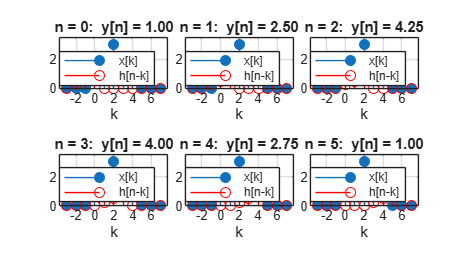

x = [1 2 3 2 1];  h = [1 0.5 0.25];
y = conv(x,h);
k = -3:7;                                      % summation index axis
xk = zeros(size(k));  xk(ismember(k,0:4)) = x;
figure('Position',[100 100 1100 600]);
tiledlayout(2,3,'TileSpacing','compact');
for n0 = 0:5
    hf = zeros(size(k));                       % h[n0-k]
    for ii = 1:numel(k)
        m = n0 - k(ii);
        if m>=0 && m<=2, hf(ii) = h(m+1); end
    end
    nexttile; stem(k,xk,'filled'); hold on; stem(k,hf,'r');
    title(sprintf('n = %d:  y[n] = %.2f',n0,sum(xk.*hf)));
    xlabel('k'); legend('x[k]','h[n-k]','Location','northeast'); ylim([0 3.5]); grid on;
end

Properties: commutative (x*h = h*x), associative, distributive, and delta[n] is the identity. Another important view: convolution of sequences is the same as multiplication of polynomials in z^-1.

x = randn(1,6); h = randn(1,4); g = randn(1,5);
comm  = max(abs(conv(x,h) - conv(h,x)))

comm = 0

assoc = max(abs(conv(conv(x,h),g) - conv(x,conv(h,g))))

assoc = 4.4409e-16

dist  = max(abs(conv(x,h(1:4)+h) - (conv(x,h(1:4))+conv(x,h))))

dist = 0

ident = max(abs(conv(x,1) - x))

ident = 0


% polynomial view: (1 + 2z^-1)(1 + 3z^-1 + z^-2) = 1 + 5z^-1 + 7z^-2 + 2z^-3
conv([1 2],[1 3 1])

ans =      1     5     7     2


## 4.2 Cross-correlation

Cross-correlation measures how similar x is to a shifted version of y (it is a 'similarity versus lag' function):


$$r_{xy}[l] = \sum_{n=-\infty}^{\infty} x[n+l]\, y^{*}[n]$$


(this is MATLAB's xcorr(x,y) convention). Link to convolution: r_xy[l] = x[l] * y*[-l], i.e. convolve with the time-reversed (and conjugated) signal. Unlike convolution it is NOT commutative: r_xy[l] = r_yx[-l]. r_xy[l] peaks at l = +D when x is a copy of y delayed by D samples (x[n] = y[n-D]), and at l = -D when y is the delayed copy.

Convolution versus correlation, side by side:

- Convolution: FLIP one signal, slide, multiply, sum. It describes what a system does to a signal.

- Correlation: DO NOT flip, just slide y over x, multiply, sum. It measures similarity at each shift l.

- Link: correlation is a convolution with the reversed signal:


$$r_{xy}[l] = x[l] * y^{*}[-l]$$


How to compute r_xy[l] by hand. Take x[n] = {1, 2, 3} and y[n] = {1, -1, 2}, both at n = 0..2. Lags run from -(Ny-1) = -2 to Nx-1 = 2. For each lag, shift y so that y[n] sits under x[n+l], multiply overlapping samples and add:


$$r_{xy}[-2] = x[0]y[2] = 2$$



$$r_{xy}[-1] = x[0]y[1] + x[1]y[2] = -1 + 4 = 3$$



$$r_{xy}[0] = x[0]y[0] + x[1]y[1] + x[2]y[2] = 1 - 2 + 6 = 5$$



$$r_{xy}[1] = x[1]y[0] + x[2]y[1] = 2 - 3 = -1$$



$$r_{xy}[2] = x[2]y[0] = 3$$


Result: r_xy = {2, 3, 5, -1, 3} for l = -2..2. Verify with the three routes below: the definition, convolution with the reversed signal, and the helper function.

x = [1 2 3];   y = [1 -1 2];
lags = -(numel(y)-1):(numel(x)-1);

r_def  = mycorr_direct(x,y)                 % straight from the definition (double loop)
r_conv = conv(x, fliplr(y))                 % x[l] * y[-l]
[r_fun,lags_fun] = mycorr(x,y)              % helper used in the rest of the notebook
disp(lags)

Reading the peak: with this convention (same as MATLAB xcorr(x,y)) the peak lag tells you who is delayed. In the test below y is x delayed by 4 samples, so r_xy peaks at l = -4, and swapping the arguments flips the sign.

x = [0 0 1 3 2 1 0 0 0 0];
y = [0 0 0 0 0 0 1 3 2 1];                   % same shape, delayed by 4 samples

[r,lags] = mycorr(x,y);   [~,i] = max(r);   lagpeak = lags(i)    % <-- expect -4: x leads y

lagpeak = -4

[r2,lags2] = mycorr(y,x); [~,i2] = max(r2); lagpeak2 = lags2(i2) % <-- +4: y lags x

lagpeak2 = 4

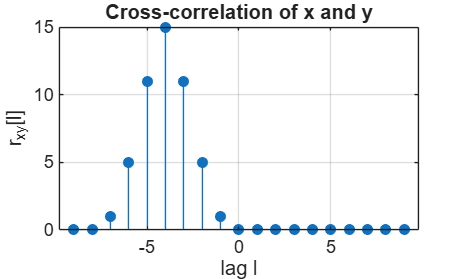


figure; stem(lags,r,'filled'); grid on; xlabel('lag l'); ylabel('r_{xy}[l]');
title('Cross-correlation of x and y');


if exist('xcorr','file')                      % compare with Signal Processing Toolbox
    [rt,lt] = xcorr(x,y);
    fprintf('Difference with xcorr: %.2e\n', max(abs(rt-r)));
end

Difference with xcorr: 1.78e-15


## 4.3 Auto-correlation


$$r_{xx}[l] = \sum_{n=-\infty}^{\infty} x[n+l]\, x^{*}[n]$$


Properties: (i) symmetric, r_xx[l] = r_xx[-l]; (ii) maximum at l = 0, where r_xx[0] equals the signal energy; (iii) periodic signals have periodic auto-correlation; (iv) white noise has r_xx approximately an impulse at l = 0; (v) its z-transform / Fourier transform gives the power (energy) spectrum.

How to compute r_xx[l] by hand: it is the cross-correlation of x with itself, so slide a copy of x over x. Take x[n] = {1, 2, 3}:


$$r_{xx}[0] = 1^2 + 2^2 + 3^2 = 14 \quad (\text{the energy})$$



$$r_{xx}[\pm 1] = x[0]x[1] + x[1]x[2] = 2 + 6 = 8$$



$$r_{xx}[\pm 2] = x[0]x[2] = 3$$


Result: r_xx = {3, 8, 14, 8, 3} for l = -2..2: symmetric, with the maximum 14 at l = 0.

For long (finite) records we normally estimate r_xx and normalise it. Two common normalisations (N = record length):


$$\hat r_{xx}[l] = \frac{1}{N}\sum_{n=0}^{N-1-|l|} x[n+|l|]\,x[n] \quad(\text{biased}), \qquad \rho_{xx}[l] = \frac{r_{xx}[l]}{r_{xx}[0]} \quad(\text{coefficient, } \rho_{xx}[0]=1)$$


x = [1 2 3];
[r,lags] = mycorr(x,x)                       % expect [3 8 14 8 3]

r =      3     8    14     8     3


lags =     -2    -1     0     1     2


rho = r / r(lags==0)                         % normalised: value 1 at lag 0

rho =     0.2143    0.5714    1.0000    0.5714    0.2143


x = [1 2 3 2 1];
[r,lags] = mycorr(x,x);
energy = sum(x.^2)

energy = 19

r0 = r(lags==0)

r0 = 19

symmetry = max(abs(r - fliplr(r)))

symmetry = 0

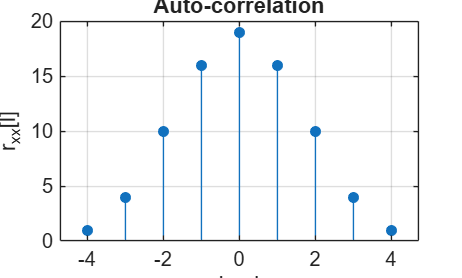

figure; stem(lags,r,'filled'); grid on; xlabel('lag l'); ylabel('r_{xx}[l]'); title('Auto-correlation');

## 4.4 The same three operations in the z-domain

Every time-domain operation above has a simple z-domain counterpart. Remember the two rules: the transform of x[n] is X(z) = sum x[n] z^-n, and time reversal x[-n] maps to X(z^-1) (substitute m = -n in the sum).


$$\mathcal{Z}\{y[-n]\} = \sum_n y[-n] z^{-n} = \sum_m y[m] z^{m} = Y(z^{-1})$$


Summary table (real signals):

- Convolution: y[n] = x[n] * h[n]  [-](http://-) Y(z) = X(z) H(z)

- Cross-correlation: r_xy[l]  [-](http://-) R_xy(z) = X(z) Y(z^-1)

- Auto-correlation: r_xx[l]  [-](http://-) R_xx(z) = X(z) X(z^-1)

(for complex signals replace Y(z^-1) by Y*(1/z*)). The ROC of a correlation is the intersection of the ROC of X(z) and the reciprocal of the ROC of Y(z).

## Convolution in the z-domain

Convolution becomes multiplication. Derivation: substitute the convolution sum into the transform and swap the order of summation:


$$Y(z) = \sum_n \Big(\sum_k x[k]h[n-k]\Big) z^{-n} = \sum_k x[k] z^{-k} \sum_m h[m] z^{-m} = X(z)\,H(z)$$


Hand example (same signals as before): X(z) = 1 + 2z^-1 + 3z^-2 + 2z^-3 + z^-4 and H(z) = 1 + 0.5z^-1 + 0.25z^-2. Multiplying the polynomials term by term gives


$$Y(z) = 1 + 2.5z^{-1} + 4.25z^{-2} + 4z^{-3} + 2.75z^{-4} + z^{-5} + 0.25z^{-6}$$


whose coefficients are exactly y[0..6] computed earlier. This is why a cascade of systems has H(z) = H1(z) H2(z), and why dividing by H(z) undoes a filter (deconvolution). Verify numerically at an arbitrary test point z0:

x = [1 2 3 2 1];  h = [1 0.5 0.25];
y = conv(x,h);                                  % time-domain convolution
Zc = @(s,z) sum(s .* z.^(-(0:numel(s)-1)));     % X(z) of a causal sequence s[0], s[1], ...
z0 = 1.3*exp(1j*0.9);                           % any test point (z0 ~= 0)

lhs = Zc(y,z0)                                  % transform of the convolution

lhs = -0.9093 - 4.0042i

rhs = Zc(x,z0) * Zc(h,z0)                       % product of the transforms

rhs = -0.9093 - 4.0042i

abs(lhs-rhs)                                    % ~ 1e-15

ans = 9.4857e-16

## Cross-correlation in the z-domain

Since r_xy[l] = x[l] * y[-l] (convolution of x with the reversed y), the convolution rule and the time-reversal rule give


$$R_{xy}(z) = X(z)\, Y(z^{-1})$$


Hand example: x = {1, 2, 3}, y = {1, -1, 2}. Then X(z) = 1 + 2z^-1 + 3z^-2 and Y(z^-1) = 1 - z + 2z^2. Multiply:


$$R_{xy}(z) = 2z^{2} + 3z^{1} + 5 - z^{-1} + 3z^{-2}$$


The coefficient of z^-l is r_xy[l]: z^2 [-](http://-) l = -2, z^1 [-](http://-) l = -1, z^0 [-](http://-) l = 0, z^-1 [-](http://-) l = 1, z^-2 [-](http://-) l = 2. So r_xy = {2, 3, 5, -1, 3}, matching the hand calculation in 4.2. Note the polynomial has both positive and negative powers of z (a two-sided sequence).

x = [1 2 3];   y = [1 -1 2];
[r,lags] = mycorr(x,y);                         % r_xy[l] in the time domain
Zl = @(s,lg,z) sum(s .* z.^(-lg));              % transform of a sequence s on lag axis lg
z0 = 1.3*exp(1j*0.9);

lhs = Zl(r,lags,z0)                             % transform of r_xy

lhs = 5.7749 + 5.2204i

rhs = Zl(x,0:2,z0) * Zl(y,0:2,1/z0)             % X(z) * Y(1/z)

rhs = 5.7749 + 5.2204i

abs(lhs-rhs)

ans = 1.9860e-15

Practical meaning: cross-correlating with a known pulse p[n] (the matched filter in the sonar example) is the same as filtering with the reversed pulse, i.e. a system with H(z) = P(z^-1), whose zeros are the reciprocals of the zeros of P(z).

## Auto-correlation in the z-domain

Set y = x in the previous result:


$$R_{xx}(z) = X(z)\, X(z^{-1})$$


Hand example: x = {1, 2, 3}. X(z) X(z^-1) = (1 + 2z^-1 + 3z^-2)(1 + 2z + 3z^2) = 3z^2 + 8z + 14 + 8z^-1 + 3z^-2, which gives r_xx = {3, 8, 14, 8, 3}, as before.

Three consequences of R_xx(z) = X(z) X(z^-1):

1. R_xx(z) = R_xx(z^-1): the auto-correlation is symmetric in l, and its poles and zeros come in reciprocal pairs (p, 1/p). 2. On the unit circle z = exp(j*w) we get the energy spectral density (Wiener-Khinchin relation): the auto-correlation and the squared magnitude spectrum are a Fourier pair.


$$R_{xx}(e^{j\omega}) = X(e^{j\omega})\,X(e^{-j\omega}) = \left|X(e^{j\omega})\right|^{2} = \sum_{l} r_{xx}[l]\, e^{-j\omega l}$$


3. Parseval at lag 0: the energy is the area under the spectrum.


$$r_{xx}[0] = \sum_n x^2[n] = \frac{1}{2\pi}\int_{-\pi}^{\pi} \left|X(e^{j\omega})\right|^2 d\omega$$


x = [1 2 3];
[r,lags] = mycorr(x,x);
Zl = @(s,lg,z) sum(s .* z.^(-lg));
z0 = 1.3*exp(1j*0.9);
abs( Zl(r,lags,z0) - Zl(x,0:2,z0)*Zl(x,0:2,1/z0) )     % R_xx(z) = X(z) X(1/z)

ans = 4.4409e-15


w  = linspace(-pi,pi,1024);
Rw = arrayfun(@(wk) Zl(r,lags,exp(1j*wk)),   w);       % R_xx on the unit circle
Xw = arrayfun(@(wk) Zl(x,0:2,exp(1j*wk)),     w);       % X on the unit circle
max_diff = max(abs(real(Rw) - abs(Xw).^2))              % |X|^2 equals R_xx(e^jw)

max_diff = 2.1316e-14

energy_freq = trapz(w,abs(Xw).^2)/(2*pi)                % Parseval: = 14 = sum(x.^2)

energy_freq = 14

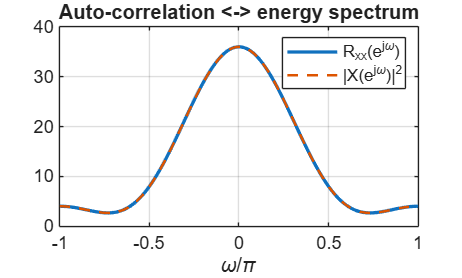


figure; plot(w/pi,real(Rw),'LineWidth',2); hold on; plot(w/pi,abs(Xw).^2,'--');
grid on; xlabel('\omega/\pi'); legend('R_{xx}(e^{j\omega})','|X(e^{j\omega})|^2'); title('Auto-correlation <-> energy spectrum');

Infinite-length example. For x[n] = a^n u[n] (`a` < 1), X(z) = 1/(1 - a z^-1), so


$$R_{xx}(z) = \frac{1}{(1 - a z^{-1})(1 - a z)}, \qquad \text{poles at } z = a \text{ and } z = 1/a, \quad a < |z| < \tfrac{1}{a}$$


Inverting by partial fractions (the ROC is the ring between the two poles) gives a two-sided exponential:


$$r_{xx}[l] = \frac{a^{|l|}}{1 - a^2}$$


a = 0.7;   N = 80;   n = 0:N-1;
x = a.^n;                                        % truncated a^n u[n]
[r,lags] = mycorr(x,x);
r_theory = a.^abs(lags)/(1-a^2);                 % inverse z-transform of R_xx(z)
sel = abs(lags) <= 20;
max_err = max(abs(r(sel) - r_theory(sel)))       % tiny (truncation only)

w = linspace(0,pi,400);
S_formula = 1./(1 - 2*a*cos(w) + a^2);           % |X(e^jw)|^2 = R_xx on the unit circle
S_from_r  = arrayfun(@(wk) sum(r.*exp(-1j*wk*lags)), w);

th = linspace(0,2*pi,400);
figure('Position',[100 100 1000 330]);
subplot(1,3,1); stem(lags(sel),r(sel),'filled'); grid on; xlabel('l'); title('r_{xx}[l] = a^{|l|}/(1-a^2)');
subplot(1,3,2); plot(w/pi,S_formula,w/pi,real(S_from_r),'--'); grid on; xlabel('\omega/\pi'); title('Spectrum from formula vs from r_{xx}');
subplot(1,3,3); plot(cos(th),sin(th),'k--'); hold on; plot([a 1/a],[0 0],'x','MarkerSize',10,'LineWidth',2);
axis equal; grid on; xlim([-1.8 1.8]); ylim([-1.8 1.8]); title('Poles of R_{xx}(z): a and 1/a'); xlabel('Re(z)');

## 5. Real applied examples

## 5.1 Convolution (a): smoothing a noisy sensor with a moving-average filter

A temperature sensor logs one sample per second. The true temperature changes slowly, but the readings carry noise. A moving-average (FIR) filter h[n] = (1/M) for 0 <= n < M is a convolution. A longer window removes more noise but blurs real changes (a trade-off). Change M.

t     = 0:299;
clean = 20 + 3*sin(2*pi*t/150) + 2*(t>150);       % true temperature (deg C) with a step at t=150
noisy = clean + 0.8*randn(size(t));

figure('Position',[100 100 900 420]); plot(t,noisy,'Color',[0.75 0.75 0.75]); hold on;
%plot(t,clean,'k','LineWidth',2);
for M = [5 25]                                    % <-- window lengths
    h  = ones(1,M)/M;
    ys = conv(noisy,h,'same');                    % 'same' keeps the length of the input
    %plot(t,ys,'LineWidth',1.5,'DisplayName',sprintf('M = %d',M));
end
legend('noisy','true','M = 5','M = 25','Location','southeast'); xlabel('time (s)'); ylabel('deg C');

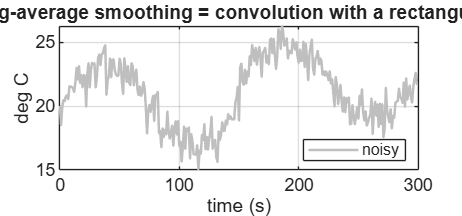

title('Moving-average smoothing = convolution with a rectangular h[n]'); grid on;

## 5.1 Convolution (b): echo / reverberation

A room acts as an LTI system. Its impulse response is a direct sound plus delayed, attenuated reflections. The recorded sound is the convolution of the dry sound with the room's h[n].

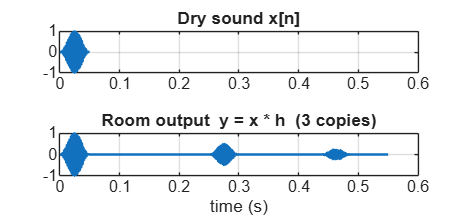

fs = 8000;
tt = 0:1/fs:0.05-1/fs;
burst = sin(2*pi*440*tt) .* (0.5-0.5*cos(2*pi*tt/0.05));    % 50 ms tone burst, smooth envelope

h = zeros(1,4000);
h(1)    = 1;          % direct path
h(2001) = 0.5;        % echo after 0.25 s, half the amplitude
h(3501) = 0.25;       % echo after 0.4375 s

y = conv(burst,h);
ty = (0:numel(y)-1)/fs;

figure('Position',[100 100 900 420]);
subplot(2,1,1); plot((0:numel(burst)-1)/fs,burst); title('Dry sound x[n]'); xlim([0 0.6]); grid on;
subplot(2,1,2); plot(ty,y); title('Room output  y = x * h  (3 copies)'); xlim([0 0.6]); xlabel('time (s)'); grid on;

sound(y,fs)   % <-- uncomment to listen

## 5.2 Cross-correlation: sonar / radar range finding

A transmitter sends a known chirp pulse p[n]. The receiver records echoes buried in noise, delayed by D = 2d/c. The echoes cannot be seen by eye, but cross-correlating the recording with the known pulse (a 'matched filter') produces a sharp peak at the delay. Distance = c * D / (2 fs).

fs = 20e3;  c = 343;                                   % sample rate (Hz), speed of sound (m/s)
T  = 5e-3;  tp = 0:1/fs:T-1/fs;
f0 = 1000;  f1 = 5000;  kk = (f1-f0)/T;
p  = sin(2*pi*(f0*tp + 0.5*kk*tp.^2));                 % linear chirp (known transmitted pulse)

Nrec = 8000;  rx = zeros(1,Nrec);
d_true = [25 40];  amp = [0.6 0.4];                  % two targets (m) and echo amplitudes
for q = 1:2
    D = round(2*d_true(q)/c*fs);
    rx(D+1:D+numel(p)) = rx(D+1:D+numel(p)) + amp(q)*p;
end
rx = rx + 0.5*randn(1,Nrec);                           % strong noise

[r,lags] = mycorr(rx,p);                               % matched filter
r  = r(lags>=0);  lags = lags(lags>=0);

[~,i1] = max(abs(r));   r2 = r;  r2(max(1,i1-100):min(end,i1+100)) = 0;   % remove 1st peak
[~,i2] = max(abs(r2));
dist_est = c*lags([i1 i2])/(2*fs)

dist_est =    24.9961   40.0024


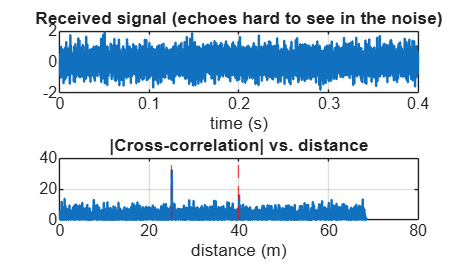


figure('Position',[100 100 900 520]);
subplot(2,1,1); plot((0:Nrec-1)/fs,rx); title('Received signal (echoes hard to see in the noise)'); xlabel('time (s)'); grid on;
subplot(2,1,2); plot(c*lags/(2*fs),abs(r)); title('|Cross-correlation| vs. distance'); xlabel('distance (m)'); grid on;
hold on; xline(d_true(1),'r--'); xline(d_true(2),'r--');

## 5.3 Auto-correlation: finding a hidden period in noise

A machine vibrates at an unknown frequency, but the sensor signal is dominated by noise. The auto-correlation of a periodic signal also peaks at multiples of the period, while noise only contributes at lag 0. Compare with pure noise.

fs = 1000;  N = 1000;  t = (0:N-1)/fs;
f_hidden = 25;                                          % Hz (pretend we don't know it)
x     = sin(2*pi*f_hidden*t) + 2*randn(1,N);            % signal power 0.5, noise power 4
noise = 2*randn(1,N);

[rx,lags] = mycorr(x,x);      rx = rx/rx(lags==0);
rn        = mycorr(noise,noise); rn = rn/rn(lags==0);

sel = lags>=10 & lags<=100;                             % ignore the lag-0 spike
[~,i] = max(rx(sel));  lagsel = lags(sel);
T_est = lagsel(i)/fs;
fprintf('Estimated period = %.1f ms  ->  frequency = %.1f Hz\n',1000*T_est,1/T_est);

Estimated period = 42.0 ms  ->  frequency = 23.8 Hz


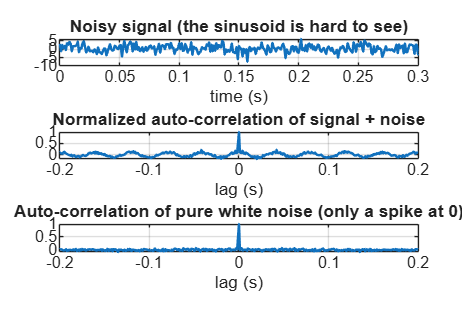


figure('Position',[100 100 900 600]);
subplot(3,1,1); plot(t,x); xlim([0 0.3]); title('Noisy signal (the sinusoid is hard to see)'); xlabel('time (s)'); grid on;
subplot(3,1,2); plot(lags/fs,rx); xlim([-0.2 0.2]); title('Normalized auto-correlation of signal + noise'); xlabel('lag (s)'); grid on;
subplot(3,1,3); plot(lags/fs,rn); xlim([-0.2 0.2]); title('Auto-correlation of pure white noise (only a spike at 0)'); xlabel('lag (s)'); grid on;

## 6. Introduction to feedback

In a feedback system part of the output is fed back and combined with the input. With negative feedback:


$$T(z) = \frac{Y(z)}{R(z)} = \frac{G(z)}{1 + G(z)F(z)}$$


where G is the forward path and F is the feedback path. Why does it matter?

- Feedback moves the poles. Poles of T(z) are the roots of 1 + G(z)F(z) = 0, not the poles of G, so we can stabilize or destabilize a system, speed it up or slow it down.

- Feedback reduces sensitivity to disturbances and parameter changes (at the cost of possible instability).

- Even the simple recursive filter y[n] = a y[n-1] + x[n] of Section 1 is a feedback system: the output goes back through z^-1 and a.

## 6.1 Example: proportional control of an accumulator

Plant: y[n+1] = y[n] + u[n] (e.g. a tank level, a bank balance or a position, where the control action u adds to the state). G(z) = 1/(z-1), a pole at z = 1 (marginally stable: an integrator).

Controller: u[n] = K (r[n] - y[n]), a gain applied to the error between reference and output.

Closed loop: y[n+1] = (1-K) y[n] + K r[n], T(z) = K/(z - (1-K)). The pole moves to z = 1-K, so the loop is stable if and only if 0 < K < 2.

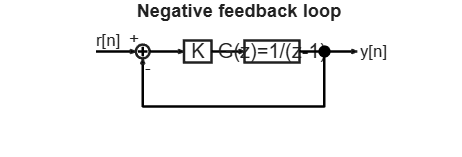

figure('Position',[100 100 880 300]);
ax = axes; hold(ax,'on'); axis(ax,[0 11 0 4]); daspect(ax,[1 1 1]); axis(ax,'off');
drawArrow(ax,[0.3 1.75],[3 3]);   text(ax,0.3,3.4,'r[n]');
drawSum(ax,2,3,0.25);             text(ax,1.5,3.45,'+'); text(ax,2.1,2.4,'-');
drawArrow(ax,[2.25 3.5],[3 3]);   drawBox(ax,4,3,1,0.8,'K');
drawArrow(ax,[4.5 5.7],[3 3]);    drawBox(ax,6.7,3,2,0.8,'G(z)=1/(z-1)');
drawArrow(ax,[7.7 9.8],[3 3]);    text(ax,9.9,3,'y[n]');
plot(ax,8.6,3,'k.','MarkerSize',22);
drawArrow(ax,[8.6 8.6 2 2],[3 1 1 2.75]);
title(ax,'Negative feedback loop');

Simulate the step response for different gains K. Observe: K small = slow; K near 1 = fastest (deadbeat); 1<K<2 = oscillating but decaying; K>2 = unstable.

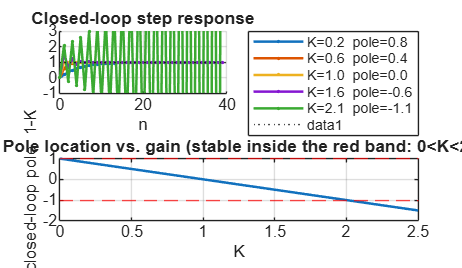

Ks = [0.2 0.6 1.0 1.6 2.1];            % <-- try your own gains
N  = 40;  n = 0:N-1;
r  = ones(1,N);  d = zeros(1,N);       % unit-step reference, no disturbance
figure('Position',[100 100 900 520]);
subplot(2,1,1); hold on;
for K = Ks
    y = simP(K,r,d);
    plot(n,y,'.-','DisplayName',sprintf('K=%.1f  pole=%.1f',K,1-K));
end
yline(1,'k:'); ylim([-1 3]); grid on; legend('Location','eastoutside'); title('Closed-loop step response'); xlabel('n');

subplot(2,1,2); Kgrid = linspace(0,2.5,200);
plot(Kgrid,1-Kgrid); hold on; yline(1,'r--'); yline(-1,'r--'); grid on;
xlabel('K'); ylabel('closed-loop pole  1-K'); title('Pole location vs. gain (stable inside the red band: 0<K<2)');

Open-loop comparison and the effect of a disturbance. With open loop (u = r), a step reference makes the accumulator ramp forever. With feedback, y follows r. Now add a constant disturbance d (e.g. a leak) entering at n = 30. Steady state: K (r - y) + d = 0, so the error is d/K. A larger gain leaves less error, but K must remain below 2.

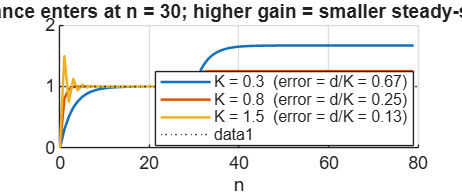

N = 80;  n = 0:N-1;
r = ones(1,N);
d = 0.2*(n>=30);                         % constant disturbance after n = 30

figure('Position',[100 100 900 380]); hold on;
for K = [0.3 0.8 1.5]
    y = simP(K,r,d);
    plot(n,y,'DisplayName',sprintf('K = %.1f  (error = d/K = %.2f)',K,0.2/K));
end
yline(1,'k:'); grid on; legend('Location','best'); xlabel('n');
title('Disturbance enters at n = 30; higher gain = smaller steady-state error');

## Summary

- A system = difference equation = block diagram (delay, gain, adder).

- CT -> DT: ZIR (initial conditions, poles only), h[n] (response to delta[n]), ZSR = x * h (sum instead of integral).

- H(z) = B(z)/A(z); poles inside the unit circle if and only if BIBO stable (causal LTI).

- Convolution gives the output; cross-correlation measures similarity/delay; auto-correlation reveals periodicity and spectrum.

- In the z-domain: convolution -> Y = X H; cross-correlation -> R_xy = X(z) Y(1/z); auto-correlation -> R_xx = X(z) X(1/z), which equals `X`^2 on the unit circle.

- Feedback changes the closed-loop poles: T = G/(1+GF).

## Exercises for students

1. In Section 1.2 set a = 1 and a = -1.1. Predict the behavior before running. Confirm with the pole-zero plot from Section 3. 2. In Section 2, change the initial condition to y[-1] = -3 and the input to a sinusoid. Which of ZIR, h[n] and ZSR change? 3. Using Section 3.2 as a template, design a system with poles at 0.9*exp(+/- j*pi/3) and a zero at z = 1. Plot `H` and describe the filter. 4. In 5.1(a) compute the noise reduction (standard deviation of ys - clean) as a function of M from 1 to 40 and plot it. What is the cost? 5. In 5.2 increase the noise standard deviation until the second target can no longer be detected. How does a longer chirp (larger T) help? 6. In 5.3 replace the sinusoid by a sum of two sinusoids at 25 Hz and 60 Hz and read both frequencies from the auto-correlation. 7. Feedback: modify simP so the controller uses the previous error u[n] = K(r[n-1] - y[n-1]) (one-sample computation delay). Find the new stable range of K.

## Local functions

Helper functions used above. Live scripts require local functions to be placed at the end.

function y = runSystem(b,a,x,yinit)
% Simulates a(1)y[n] = sum_k b(k+1)x[n-k] - sum_k a(k+1)y[n-k]
% yinit = [y[-1] y[-2] ...] initial conditions (zero input history assumed)
N = numel(x);  nb = numel(b)-1;  na = numel(a)-1;
y = zeros(1,N);
for n = 1:N
    acc = 0;
    for k = 0:nb
        if n-k >= 1, acc = acc + b(k+1)*x(n-k); end
    end
    for k = 1:na
        if n-k >= 1, yk = y(n-k); else, yk = yinit(k-n+1); end
        acc = acc - a(k+1)*yk;
    end
    y(n) = acc/a(1);
end
end

function y = myconv(x,h)
% Direct implementation of the convolution sum y[n] = sum_k x[k] h[n-k]
Nx = numel(x);  Nh = numel(h);
y = zeros(1,Nx+Nh-1);
for n = 1:Nx+Nh-1
    for k = 1:Nx
        m = n-k+1;
        if m >= 1 && m <= Nh
            y(n) = y(n) + x(k)*h(m);
        end
    end
end
end

function [r,lags] = mycorr(x,y)
% Cross-correlation r_xy[l] = sum_n x[n+l] y[n]  (same convention as xcorr)
x = x(:).';  y = y(:).';
r = conv(x,fliplr(conj(y)));
lags = -(numel(y)-1):(numel(x)-1);
end

function r = mycorr_direct(x,y)
% r_xy[l] = sum_n x[n+l] y[n], straight from the definition (no flipping)
Nx = numel(x);  Ny = numel(y);
lags = -(Ny-1):(Nx-1);
r = zeros(size(lags));
for i = 1:numel(lags)
    l = lags(i);
    for n = 0:Ny-1                         % n indexes y[n], 0-based
        m = n + l;                         % index into x[n+l], 0-based
        if m >= 0 && m <= Nx-1
            r(i) = r(i) + x(m+1)*y(n+1);
        end
    end
end
end

function y = simP(K,r,d)
% Plant y[n+1] = y[n] + u[n] + d[n], proportional controller u[n] = K(r[n]-y[n])
N = numel(r);  y = zeros(1,N+1);
for n = 1:N
    u = K*(r(n)-y(n));
    y(n+1) = y(n) + u + d(n);
end
y = y(1:N);
end

function pzPlot(ax,b,a)
% Pole-zero plot of H(z) = B(z^-1)/A(z^-1) with the unit circle
nz = max(numel(b),numel(a));
bp = [b(:).' zeros(1,nz-numel(b))];
ap = [a(:).' zeros(1,nz-numel(a))];
z = roots(bp);  p = roots(ap);
th = linspace(0,2*pi,400);
plot(ax,cos(th),sin(th),'k--'); hold(ax,'on');
plot(ax,real(z),imag(z),'o','MarkerSize',9);
plot(ax,real(p),imag(p),'x','MarkerSize',10,'LineWidth',2);
axis(ax,'equal'); grid(ax,'on'); xlim(ax,[-1.6 1.6]); ylim(ax,[-1.6 1.6]);
xlabel(ax,'Re(z)'); ylabel(ax,'Im(z)');
end

function drawBox(ax,cx,cy,w,h,label)
rectangle(ax,'Position',[cx-w/2 cy-h/2 w h],'LineWidth',1.5);
text(ax,cx,cy,label,'HorizontalAlignment','center','FontSize',12);
end

function drawSum(ax,cx,cy,r)
rectangle(ax,'Position',[cx-r cy-r 2*r 2*r],'Curvature',[1 1],'LineWidth',1.5);
line(ax,[cx-r cx+r]*0.7+cx*0.3,[cy cy],'Color','k');
line(ax,[cx cx],[cy-r cy+r]*0.7+cy*0.3,'Color','k');
end

function drawArrow(ax,xs,ys)
% Polyline with an arrowhead at the final point
line(ax,xs,ys,'Color','k','LineWidth',1.5);
d = [xs(end)-xs(end-1), ys(end)-ys(end-1)];  d = d/norm(d);
nr = [-d(2) d(1)];  tip = [xs(end) ys(end)];  bs = tip - 0.2*d;
pts = [tip; bs+0.08*nr; bs-0.08*nr];
patch(ax,pts(:,1),pts(:,2),'k');
end